s = [1 1 1 1 2 2 3 4 4 5 6];
t = [2 3 4 5 3 6 6 5 7 7 7];
weights = [50 10 20 80 90 90 30 20 100 40 60];
G = graph(s,t,weights)

G =   graph with properties:

    Edges: [11×2 table]
    Nodes: [7×0 table]


k = 5

k = 5

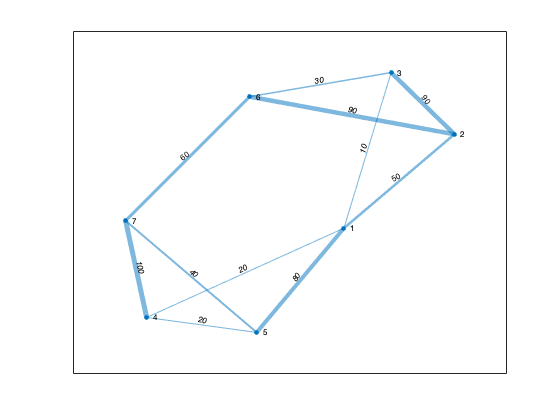

LWidths = k*G.Edges.Weight/max(G.Edges.Weight);
plot(G,'EdgeLabel',G.Edges.Weight,'LineWidth',LWidths)

s = [1 1 1 2 2 3 3 4 5 5 6 7 7 8 8 9 10 11];
t = [2 3 10 4 12 4 5 6 6 7 9 8 10 9 11 12 11 12];
G = graph(s,t)

G =   graph with properties:

    Edges: [18×1 table]
    Nodes: [12×0 table]


%i think the names have to be given to each node separately, didnt find how
%to change only one name of node
G.Nodes.Name = {'Home' ;'2'; '3'; '4'; '5'; '6'; '7'; '8'; 'Food'; '10'; '11'; '12'}

G =   graph with properties:

    Edges: [18×1 table]
    Nodes: [12×1 table]


G.Edges.Weight = rand(18,1); %to initialize weights of edges 
p = plot(G, 'Layout',"force3", "EdgeLabel",G.Edges.Weight)

p =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'Home'  '2'  '3'  '4'  '5'  '6'  '7'  '8'  'Food'  '10'  '11'  '12'}
     EdgeLabel: {'0.63932'  '0.54472'  '0.64731'  '0.54389'  '0.72105'  '0.5225'  '0.9937'  '0.21868'  '0.1058'  '0.1097'  '0.063591'  '0.40458'  '0.44837'  '0.36582'  '0.7635'  '0.6279'  '0.77198'  '0.93285'}
         XData: [2.0006 1.1874 2.0090 1.2719 0.2721 -0.5428 -0.6623 -2.1482 -1.9184 0.4577 -1.1323 -0.7946]
         YData: [-0.5428 0.2721 1.2719 2.0090 1.1874 2.0006 -0.7946 -1.1323 0.4577 -1.9184 -2.1482 -0.6623]
         ZData: [-0.0911 -1.6784 0.7217 -0.7217 1.6784 0.0911 1.7990 0.5262 -0.6448 0.6448 -0.5262 -1.7990]

  Show 

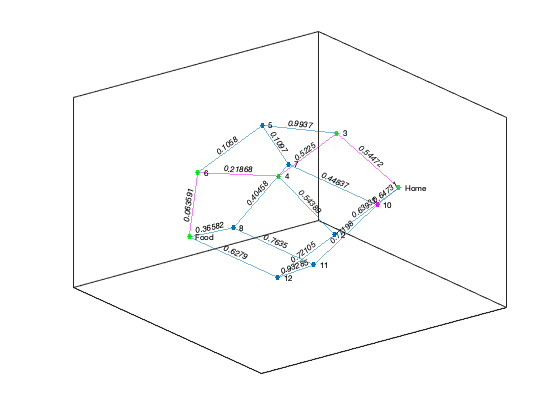

m=10;
highlight(p,m,'NodeColor',"magenta") %to highlight the node where the ant is
path = shortestpath(G,'Food','Home');
highlight(p,path,'NodeColor','g','EdgeColor','m')